# RBE502 HW2 Question 2

Author: Keith Chester

E-mail: kchester@wpi.edu

## Introduction

This file is the code portion that generates requested phase portraits for question 2 on the HW.

## Part B

With a state space formulation of $x_1 =q\;,x_2 =\dot{q}$, we found in part A that $\dot{x_1 } =x_2 \;,\dot{x_2 =\frac{\mathrm{mglsin}\left(q\right)}{{\mathrm{ml}}^2 }}$.

Now, we assume $m=0\ldotp 1\mathrm{kg},l=1m,g=9\ldotp 81\frac{m}{s^2 }$ to draw a phase portrait of the system.

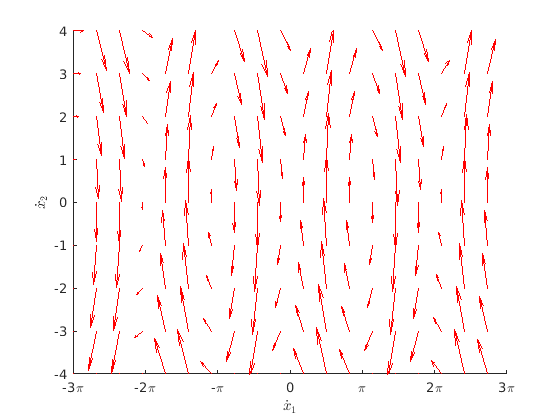

figure
hold on
xlabel('$\dot{x}_1$','interpreter','latex');
ylabel('$\dot{x}_2$','interpreter','latex');
xlim([-3*pi 3*pi]);
ylim([-4 4]);
set(gca,'XTick',-3*pi:pi:3*pi);
set(gca, 'XTickLabel',{'-3\pi','-2\pi','-\pi','0','\pi','2\pi','3\pi'});

m = 0.1;
l = 1;
g = 9.81;

[x1,x2] = meshgrid(-3*pi:3*pi,-4:4);

dx1 = x2;
dx2 = (m*g*l*sin(x1))/(m*l^2);
quiver(x1, x2, dx1, dx2, 'color', 'red')
hold off

## Part C

Now we will identify all of the equilibrium points of this system. An equilibrium point is defined as a point where $\frac{{\dot{x} }_1 }{{\dot{x} }_2 }=0$.

Since we know that ${\dot{x} }_1 =x_2$, and $x_2$ is a range from -4 to 4, there exists only a singular value where this value is 0... 0 itself. Since $\dot{x_2 } =\frac{\mathrm{mglsin}\left(x_1 \right)}{{\mathrm{ml}}^2 }$, we will result in 0 values when $\sin \left(x_1 \right)==0$, which is $c*\pi$ where *c* is an integer.

Looking at the phase portrait, we can mark each of these:

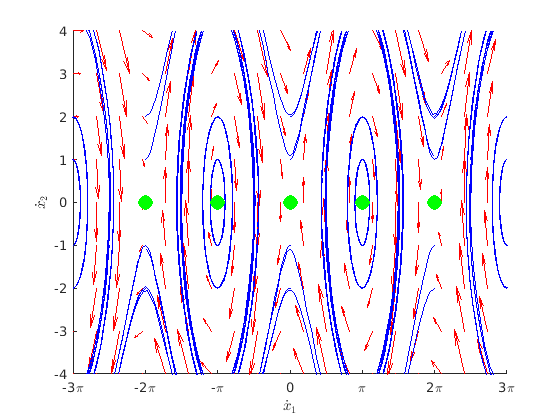

figure
hold on
xlabel('$\dot{x}_1$','interpreter','latex');
ylabel('$\dot{x}_2$','interpreter','latex');
xlim([-3*pi 3*pi]);
ylim([-4 4]);
set(gca,'XTick',-3*pi:pi:3*pi);
set(gca, 'XTickLabel',{'-3\pi','-2\pi','-\pi','0','\pi','2\pi','3\pi'});

quiver(x1, x2, dx1, dx2, 'color', 'red')

f = @(t, X) [X(2); (m*g*l*sin(X(1)))/(m*l^2);];

for x1_initial = -3*pi:pi/2:3*pi
    for x2_initial = -2:1:2
        [ts, q] = ode45(f, [0, 4],[x1_initial, x2_initial]);
        
        % Plot our line for the given initial conditions
        plot(q(:,1), q(:,2), 'Color', 'blue');
    end
end

equilibrium_points = [0 0; -pi 0; -2*pi 0;pi 0; 2*pi 0;];

plot(equilibrium_points(:,1), equilibrium_points(:,2), 'LineStyle',"none", 'Marker',"o", 'MarkerSize', 10, 'MarkerEdgeColor', "green", 'MarkerFaceColor', 'green')

hold off